Code to create the background banner for the promotional Instagram post and Facebook event page.

fig = figure;

fig =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.940000000000000 0.940000000000000 0.940000000000000]
    Position: [470 478 560 420]
       Units: 'pixels'

  Show all properties


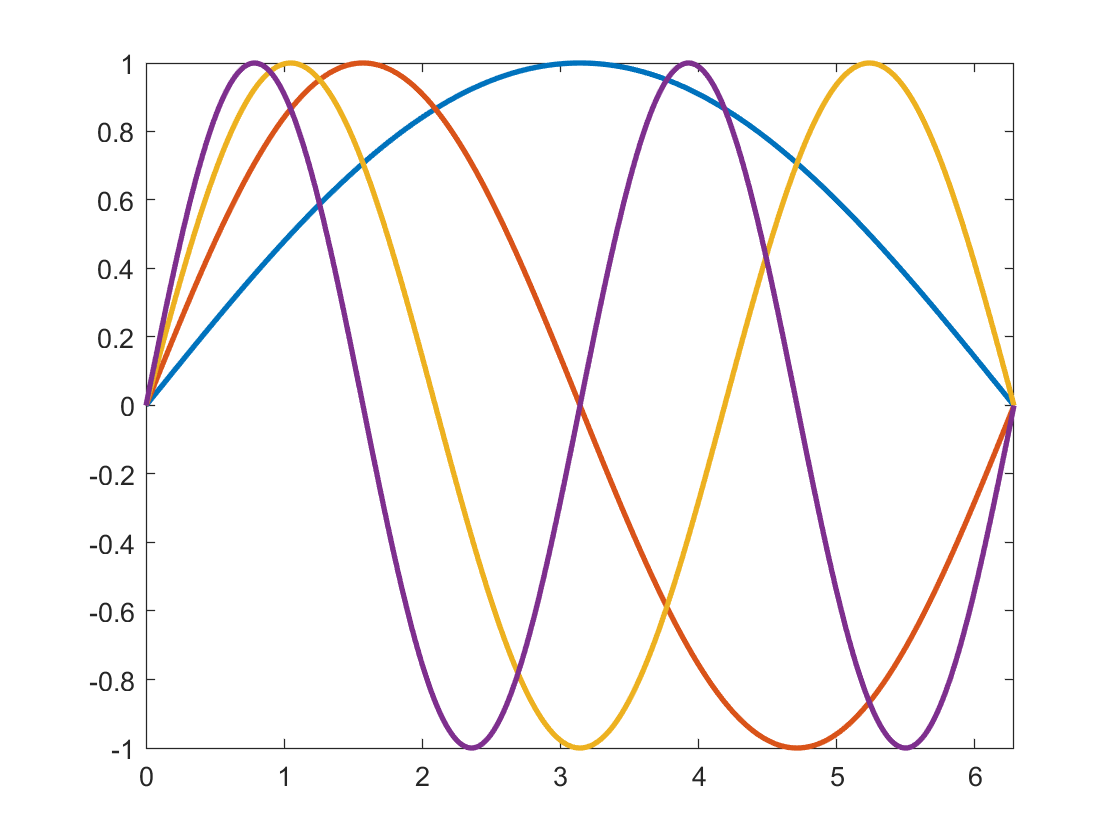

x = linspace(0, 2*pi, 500);
y = sin((0.5:0.5:2)' .* x);
plot(x, y, 'LineWidth', 2);
xlim([0, 2*pi]);
saveas(fig, 'sin.svg');

Calculate mandelbrot

res = 0.01;
complex_plane = (-2:res:1) + 1i * flip(-1.5:res:1.5).';
z = complex_plane;
counts = int64(zeros(size(complex_plane)));
for i=1:20
    region = abs(z) < 2;
    counts(region) = counts(region) + 1;
    z(region) = z(region) .^ 2 + complex_plane(region);
end

Plot mandelbrot

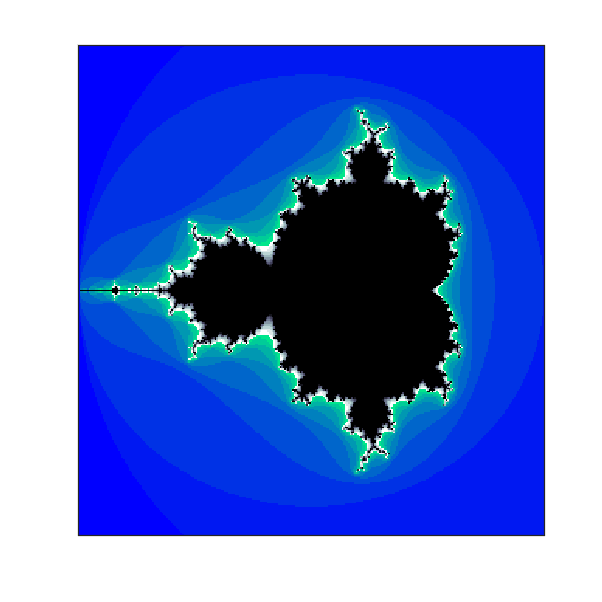

fig = figure("Position",[0 0 size(counts)]);
cmap = [winter(256/2); flip(bone(256/2))];
imagesc(counts);
colormap(fig, cmap);
xticks([]); yticks([]);
saveas(fig, 'mandelbrot.svg');

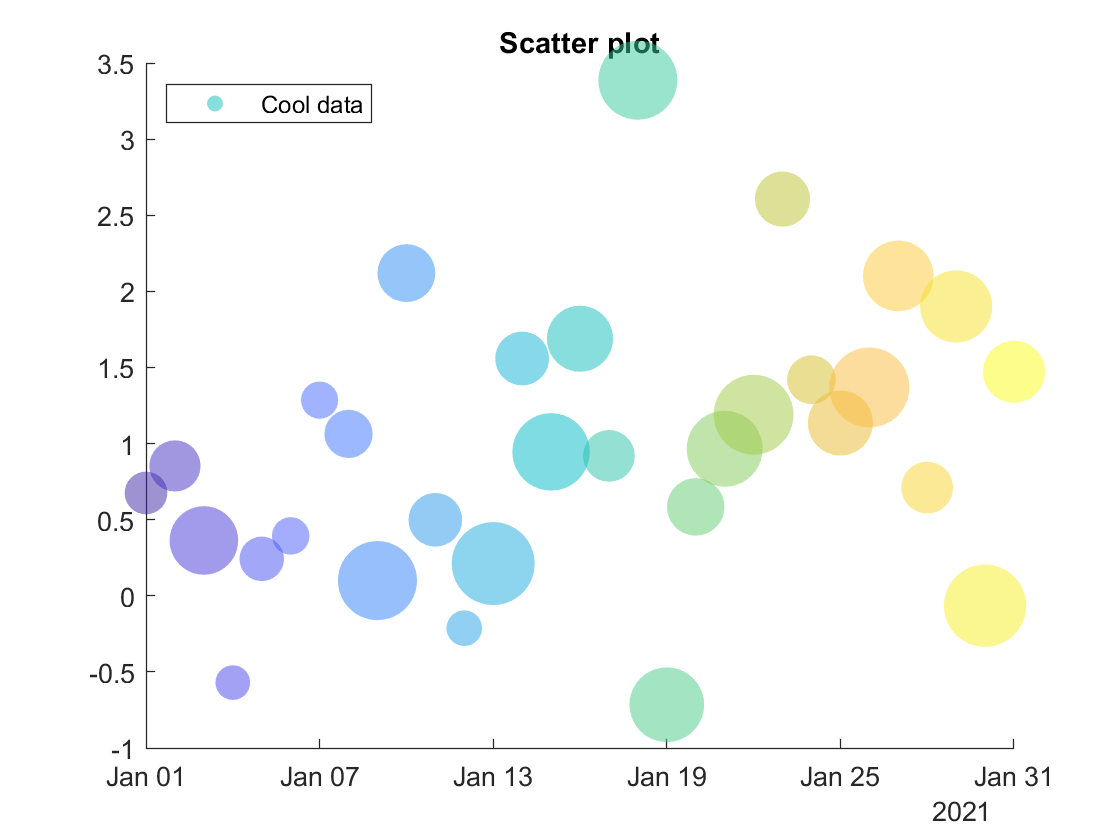

fig = figure("Name","scatter");
x = datetime(2021, 1, 1:31);
scatter(x, randn(size(x)) + x.Day ./ 20, 1000*rand(size(x)), parula(length(x)), "filled", "MarkerFaceAlpha", 0.5);
legend("Cool data", "Location","northwest");
title("Scatter plot");
saveas(fig, 'scatter.svg');

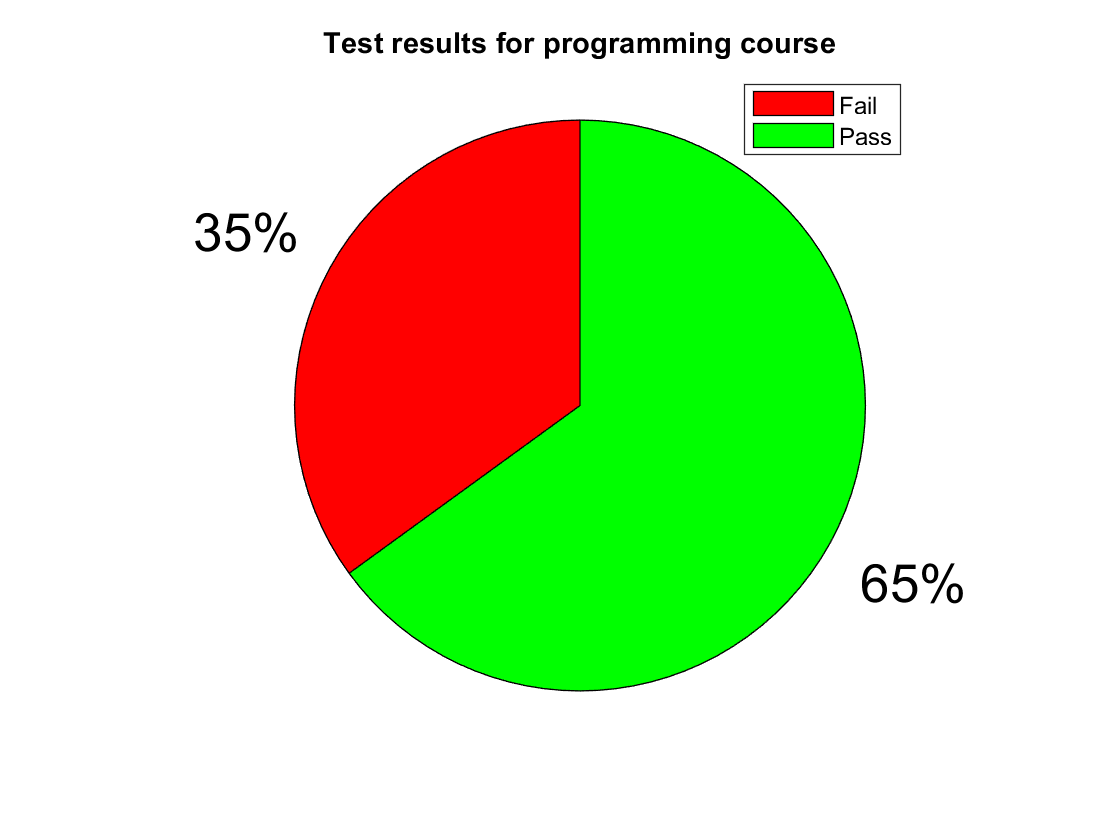

fig = figure("Name","pie");
colormap(prism);
percentage = 65;
p = pie([(1-percentage/100)*150, 150*percentage/100]);
for t=p(2:2:end)
    t.FontSize = 20;
end
legend(["Fail", "Pass"]);
title("Test results for programming course");
saveas(fig, 'pie.svg');

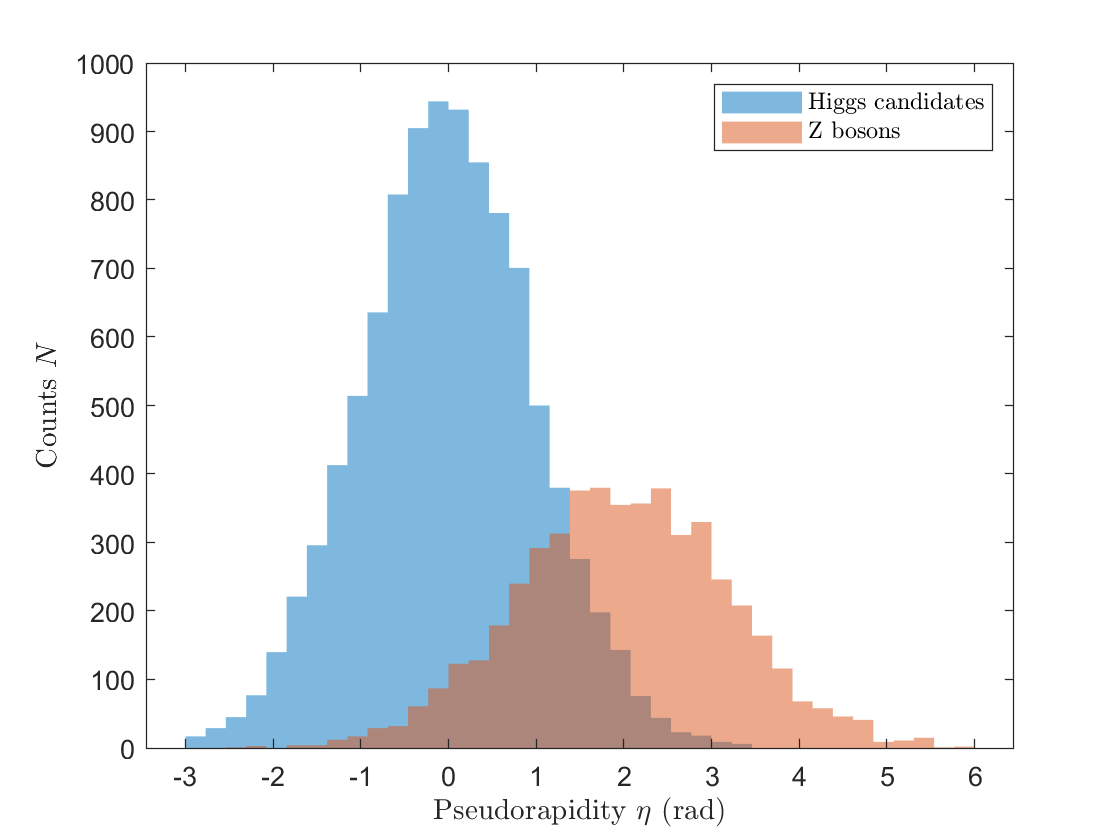

fig = figure("Name","hist");
data = randn([10000 1]);
data2 = randn([int64(length(data)/2) 1]) * 1.2 + 2;
bins = linspace(-3, 6, 40);
histogram(data, "FaceAlpha",0.5, "EdgeColor","none", "BinEdges",bins);
hold on
histogram(data2, "FaceAlpha",0.5, "EdgeColor","none", "BinEdges",bins);
hold off
xlabel("Pseudorapidity $\eta$ (rad)", "Interpreter","latex");
ylabel("Counts $N$", "Interpreter","latex");
legend(["Higgs candidates", "Z bosons"], "Interpreter","latex");
saveas(fig, 'hist.svg');

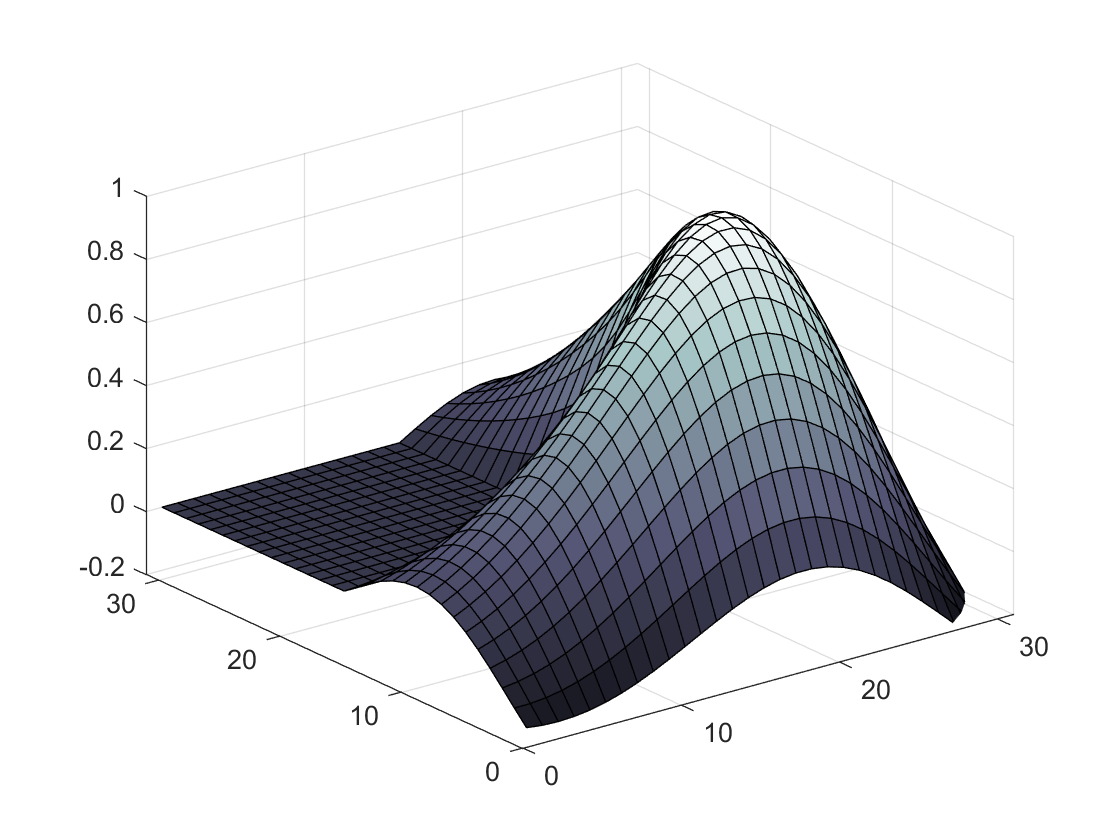

fig = figure("Name","logo");
z = membrane;
surf(z);
colormap("bone");
zlim([-0.2, 1]);
saveas(fig, 'logo.svg');